# Week02 Aliasing & Z-transform

496436  Nian luisman

** Frequency analysis**

We can already apply our knowledge of DSP to create a guitar tuning program. Read in the audio file and determine which open guitar string is being struck. The sampling frequency of the audio signal is 44100 Hz. 

[y, fs] = audioread("Week02\filename.wav")

y =     0.0002
    0.0002
    0.0003
    0.0003
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0004


fs = 44100

data = fft(y)

data = 	1.0e+03 *

   0.0000 + 0.0000i
   0.0002 - 0.0001i
   0.0002 + 0.0002i
   0.0009 - 0.0004i
   0.0004 - 0.0008i
  -0.0003 - 0.0009i
  -0.0002 - 0.0008i
  -0.0007 - 0.0008i
  -0.0009 - 0.0010i
  -0.0016 - 0.0004i


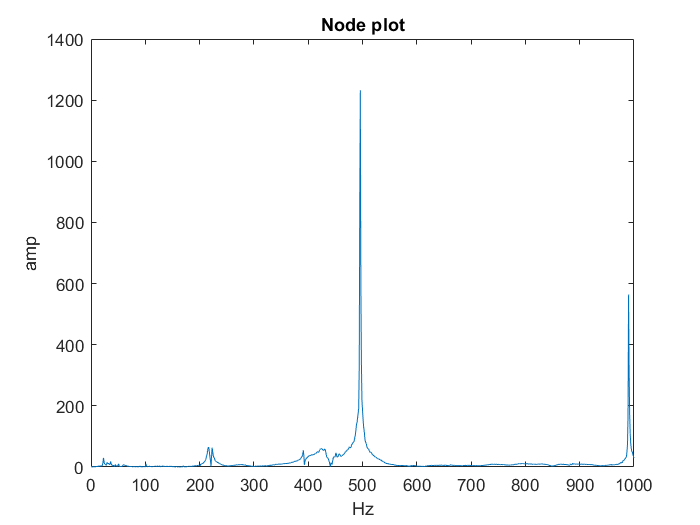

plot(abs(data(:,1)))
xlim([0,1000])
title("Node plot")
xlabel("Hz")
ylabel("amp")

Based on the plot seen above I can say the musical note is a B (493hz).

## Z-transform: manual work

**What is the z-transform of the following series: 𝑥[𝑛] = {0, 1, 2, 3, 2, 7, 0, 0, 0, 0, ⋯ }**

z(x) = z^-1 + 2Z^-1 + 3Z^-4 + 2Z^-4 + 7Z^-5

**Given the following function:**

 𝑥(𝑡) = 4𝑡 − 4𝑡 ∙ 𝑒 −3𝑡 

**a. Find 𝑥0, 𝑥1, 𝑥2, 𝑥3 (numerical values in 𝑥[𝑛]) **

Ts = 0.1

Ts = 0.1000

N = 0:1:3 

N =      0     1     2     3


t = Ts * N 

t =          0    0.1000    0.2000    0.3000


y = 4.*t - 4.*t.*exp(-3.*t)

y =          0    0.1037    0.3610    0.7121


x[n] = {0, 0.1, 0.36, 0,71}

**b. Find the z-transform of this function**

z(x) = 4Z^-1 - z  / ( z - (4*exp(-3)))

**Find the z-transform of the following function:**

 **a. 𝑥(𝑡) = 3 sin(4𝑡) + 4 cos(4𝑡) **

3*Z*(sin(4t)/(z^2*(2*Z*cos(4t)) +1 ) + 4*Z (Z*cos(4t) / (Z*2 - 2*Z *cos(4*t) +  1)

**b. 𝑥𝑘 = 7.4 𝑘 **

Z/Z-7.4

**c. 𝑥𝑘 = 7𝑘 ∙ 7 𝑘−1** 

7*z / (Z -7)^2

**Given the following transfer function in the Laplace domain:**

𝐻(𝑠) = 2𝑠 + 1 / (𝑠 + 1)(𝑠 + 2) 

**a. Perform a partial fraction expansion (NL: breuksplitsen)**

 1/(s + 1)  -  3 / (s + 2)

## Z-transform: MATLAB

Use MATLAB as much as possible for the following questions.

Ref, question 1. Plot the samples like “needles” (“dirac pulses”) 

x = [0,1,2,3,2,7,0]

x =      0     1     2     3     2     7     0


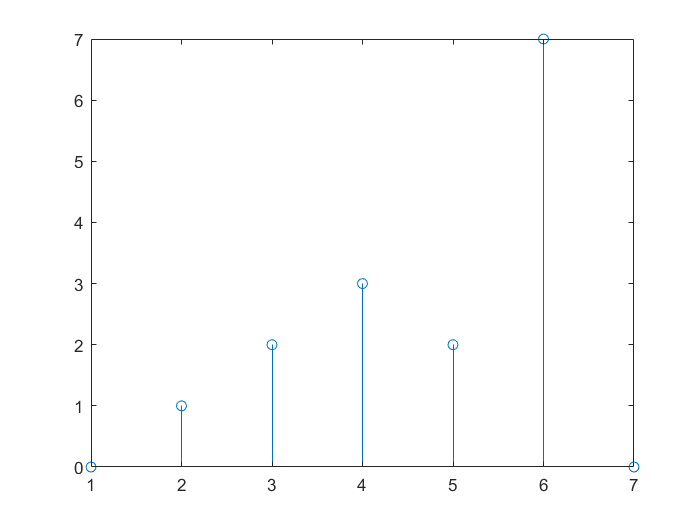

stem(x)

title("stem")
xlabel("x")
ylabel("y")

Ref, question 2. Plot the first 10 samples as a staircas

Ts = 0.1

Ts = 0.1000

N = 0:1:10 

N =      0     1     2     3     4     5     6     7     8     9    10


t = Ts * N 

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


y = 4.*t - 4.*t.*exp(-3.*t)

y =          0    0.1037    0.3610    0.7121    1.1181    1.5537    2.0033    2.4571    2.9097    3.3581    3.8009


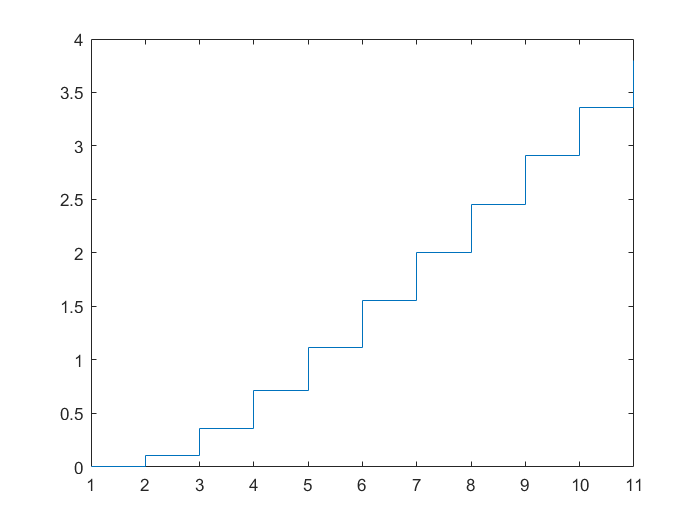

stairs(y)

title("y(x) = 4*t - 4*t*exp(-3*t)")
xlabel("x")
ylabel("y")

Ref, question 3. Let MATLAB find the answer

syms t
f = 3 .*sin(4*t) + 4 * cos(4*t)

$$f = 4\,\cos\left(4\,t\right)+3\,\sin\left(4\,t\right)$$

ztrans(f)

$$ans = \frac{3\,z\,\sin\left(4\right)}{z^{2}-2\,\cos\left(4\right)\,z+1}+\frac{4\,z\,\left(z-\cos\left(4\right)\right)}{z^{2}-2\,\cos\left(4\right)\,z+1}$$

Ref, question 3. Let MATLAB find the answer

syms k
f = 7.4^k

$$f = {\left(\frac{37}{5}\right)}^{k}$$

ztrans(f)

$$ans = \frac{z}{z-\frac{37}{5}}$$

Ref, question 3. Let MATLAB find the answer

syms k
f = 7*k * 7^(k-1)

$$f = 7\,7^{k-1}\,k$$

ztrans(f)

$$ans = \frac{7\,z}{{\left(z-7\right)}^{2}}$$